**1**

function y = convol(x, h, n)
arguments (Input)
	x
	h
	n
end

arguments (Output)
	y
end

dimh = numel(h);
dimx = numel(x);
dimy = dimx + dimh - 1;

xpadded = [zeros(1, dimh - 1) x zeros(1, dimh - 1)];
y = zeros(1, dimy);
hflipped = flip(h);

for i = 1:dimy
	y(i) = sum(xpadded(i:i+dimh - 1) .* hflipped);
end

yini = n(1) - floor(dimh / 2);
ny = yini:yini+dimy-1;
y = y((find(ny == n(1)):find(ny == n(end))));
end

**1.1**

plNum = 4

plNum = 4

b0 = 0.1 * (mod(plNum, 2) + 1)

b0 = 0.1000

b1 = 0.4 * mod(plNum, 2)

b1 = 0

b2 = 0.4 * mod(1 + plNum, 2)

b2 = 0.4000

b3 = 0.3 * (mod(plNum, 3) + 1)

b3 = 0.6000

b4 = -0.1 * (mod(plNum, 4) + 1)

b4 = -0.1000

h1n = [b0 b1 b2 b3 b4]

h1n =     0.1000         0    0.4000    0.6000   -0.1000


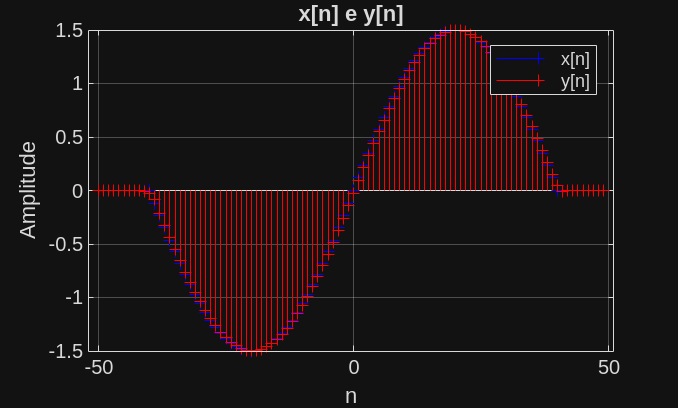


syms n
sympref('HeavisideAtOrigin',1);
x1n = 1.5 * sin(0.025 * pi * n) * (heaviside(n + 40) - heaviside(n - 41));

n1Vals = -50:49;
x1nVals = double(subs(x1n, n, n1Vals));
y1nVals = convol(x1nVals, h1n, n1Vals);

figure;
stem(n1Vals, x1nVals, '+b');
hold on;
stem(n1Vals, y1nVals, '+r');
hold off;
xlabel("n");
ylabel("Amplitude");
title("x[n] e y[n]");
legend("x[n]", "y[n]");
grid on;

**1.2**

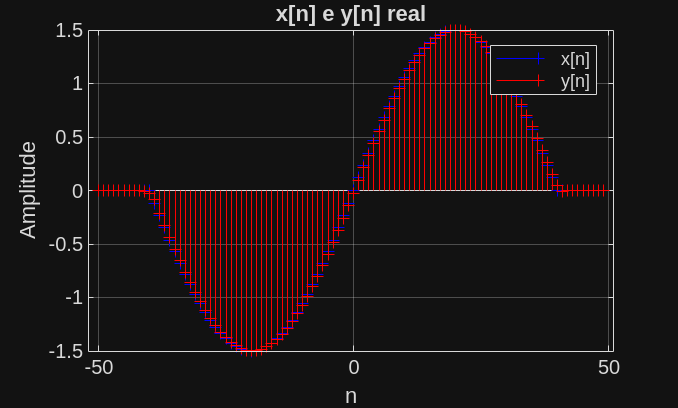

figure;
stem(n1Vals, x1nVals, '+b');
hold on;
stem(n1Vals, conv(x1nVals, h1n, 'same'), '+r');
hold off;
xlabel("n");
ylabel("Amplitude");
title("x[n] e y[n] real");
legend("x[n]", "y[n]");
grid on;

**1.3**

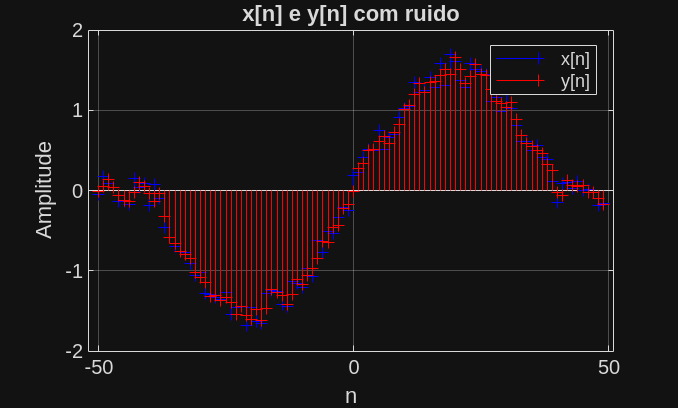

rng(42);
noise = (rand(size(x1nVals)) - 0.5) * 0.4;
x1nNoise = x1nVals + noise;
y1nNoise = convol(x1nNoise, h1n, n1Vals);

figure;
stem(n1Vals, x1nNoise, '+b');
hold on;
stem(n1Vals, y1nNoise, '+r');
hold off;
xlabel("n");
ylabel("Amplitude");
title("x[n] e y[n] com ruido");
legend("x[n]", "y[n]");
grid on;

**1.4**

`O sistema é linear, pelo que o ruído adicionado à entrada surge também na saída, filtrado pela resposta a impulso h[n]. A forma geral de y[n] é preservada, mas com pequenas flutuações de amplitude causadas pelo ruído.`

`2`

x1nFun = symfun(1.5 * sin(0.025 * pi * n) * (heaviside(n + 40) - heaviside(n - 41)), n);
y1nFun = symfun(b0*x1nFun(n) + b1*x1nFun(n-1) + ...
                b2*x1nFun(n-2) + b3*x1nFun(n-3) + ...
                b4*x1nFun(n-4), n);
y2nFun = symfun(0.6*x1nFun(2*n - 4), n);
y3nFun = symfun(0.5*x1nFun(n-2)*x1nFun(n-3), n);
y4nFun = symfun((n-2)*x1nFun(n-3), n);

**2.1**

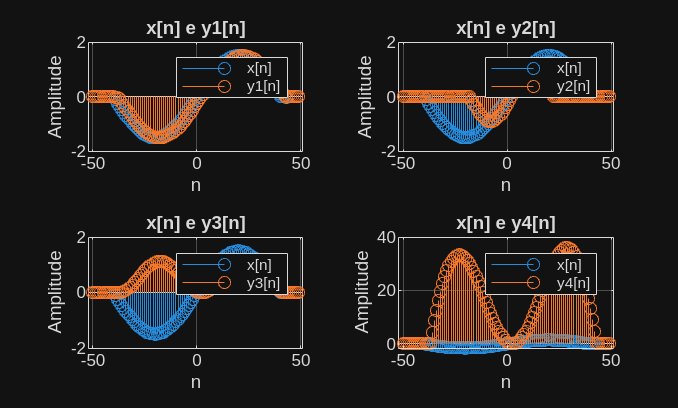

yFuncs = {y1nFun y2nFun y3nFun y4nFun};
numFuncs = numel(yFuncs);
figure;
tiledlayout(ceil(numFuncs / 2), 2);
for i = 1:numFuncs
	nexttile;
	stem(n1Vals, x1nFun(n1Vals));
	hold on;
	stem(n1Vals, yFuncs{i}(n1Vals));
	hold off;
	xlabel("n");
	ylabel("Amplitude");
	title("x[n] e y" + i +"[n]");
	legend("x[n]", "y" + i + "[n]");
	grid on;
end